CIE 2006: Chapter 2

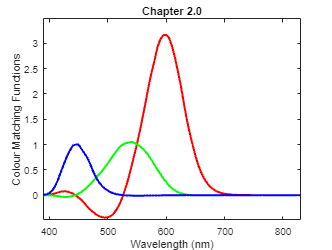

%CHAPTER 2
clc;
clear;

% Define pathways
user = getenv('username');
cd(['C:\Users\', user, '\Documents\GitHub\Arduino-Colour-Vision-Genetics']);
addpath("Conversion-Code");
addpath("Conversion-Code\tables");

% Define coefficients
constant_coefficients_normalised = [0.192325269,  0.749548882,  0.0675726702;...
                                    0.0192290085, 0.940908496,  0.113830196;...
                                    0,            0.0105107859, 0.991427669];

% Import table of colour matching functions
colour_matching_functions = table2array(readtable('sbrgb10w.csv'));
%colour_matching_functions(isnan(colour_matching_functions)) = 0;

wavelengths = colour_matching_functions(:,1);
colour_matching_functions = colour_matching_functions(:,2:end);

% Draw 'before' graph
colours = ['r', 'g', 'b'];
for cone = 1:3
    x = wavelengths;
    y = colour_matching_functions(:,cone);
    plot(x, y, "LineWidth", 2, "Color", colours(cone))
    hold on
end
xlim([min(x), max(x)]);
ylim([1.1 * min(colour_matching_functions, [], "all"),...
      1.1 * max(colour_matching_functions, [], "all")]);
xlabel("Wavelength (nm)");
ylabel("Colour Matching Functions");
title("Chapter 2.0");
hold off

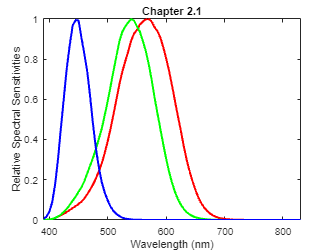


% Create table for cone fundamental values
cone_fundamentals = zeros(height(wavelengths), 3);

% For every wavelength...
for wavelength = 1:height(colour_matching_functions)
    % For each of the 3 cones...
    for lms = 1:3
        funcBits = zeros(1,3);
        % For the R, G, & B functions in the equations...
        for rgb = 1:3
            % Multiply the relevant constant by the relevant colour matching function
            funcBits(rgb) = constant_coefficients_normalised(lms,rgb) * colour_matching_functions(wavelength,rgb);
        end
        funcAns = sum(funcBits);     
        % Input result into fundamentals table
        cone_fundamentals(wavelength, lms) =  funcAns;
    end
end

% Draw 'after' graph
colours = ['r', 'g', 'b'];
for cone = 1:3
    x = wavelengths;
    y = cone_fundamentals(:,cone);
    plot(x, y, "LineWidth", 2, "Color", colours(cone))
    hold on
end
xlim([min(x), max(x)]);
ylim([0, 1]);
xlabel("Wavelength (nm)");
ylabel("Relative Spectral Sensitivities");
title("Chapter 2.1");
hold off

CIE 2006: Chapter 5

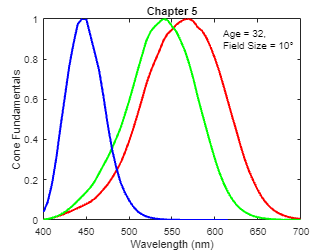

% Defining variables
field_size = 10;
age = 32;
pupil_size = "default";

cones = ['r', 'g', 'b'];

% Importing density tables
spectral_absorbance = table2array(readtable("ssabance_5.csv"));
wavelengths = spectral_absorbance(:,1);
spectral_absorbance = spectral_absorbance(:,2:end);
spectral_absorbance = 10 .^ spectral_absorbance; 
for cone = 1:length(cones)
    spectral_absorbance(:,cone) = spectral_absorbance(:,cone) ./ max(spectral_absorbance(:,cone));
end

macular_density = table2array(readtable("macPigRelative_5.csv")); % ask Allie
macular_density = macular_density(:,2:end);

lens_density = table2array(readtable("lens2components.csv")); % ask Allie
lens_density = lens_density(:,2:end); 

% Wavelengths
idx = wavelengths >= 400 & wavelengths <= 700;
wavelengths = wavelengths(idx,:);
spectral_absorbance = spectral_absorbance(idx,:);

% Lens density and pupil size
if strcmpi(pupil_size, "large") || strcmpi(pupil_size, "l")
    lens_density = lens_density .* .86207;
elseif ~strcmpi(pupil_size, "small") && ~strcmpi(pupil_size, "s") && ~strcmpi(pupil_size, "default")
    disp("Please set variable pupil_size to a valid string!");
    disp("Valid string values: ""default"", ""small"", ""s"", ""large"", ""l""");
    return;
end

% 5.3 - Peak optical density & Field Size
if field_size >= 1 && field_size <= 10
    Dt_max_macula = 0.485 .* exp(-field_size / 6.132);
else
    disp("Field size must be set between 1 and 10!");
    return
end

% 5.6 - Spectral optical density & Age
Dt_ocul = zeros(height(wavelengths),1);

if age >= 20 && age <=60
    for wavelength = 1:height(wavelengths)
        Dt_ocul(wavelength) = (lens_density(wavelength,1) * (1 + (0.02 * (age - 32)))) + lens_density(wavelength,2);
    end

elseif age > 60 && age <= 80
    for wavelength = 1:height(wavelengths)
        Dt_ocul(wavelength) = (lens_density(wavelength,1) * (1.56 + (0.0667 * (age - 60)))) + lens_density(wavelength,2);
    end

else
    disp("Age must be set between 20 and 80!");
    return
end

% 5.7 - Visual Pigments & Field Size
Dt_max = zeros(1,length(cones));
D_max_constants = [0.38, 0.54;... 
                    0.38, 0.54;... 
                    0.30, 0.45];

for cone = 1:length(cones)
    Dt_max(cone) = D_max_constants(cone,1) + D_max_constants(cone,2) * exp(-field_size / 1.333);
end

% 5.9 - Cone Fundamentals
ai_tbl = zeros(height(wavelengths), length(cones));
for wavelength = 1:height(wavelengths)
    for cone = 1:length(cones)
        ai_tbl(wavelength,cone) = 1 - (10 ^ (-Dt_max(cone) * spectral_absorbance(wavelength,cone)));
    end
end

cone_fundamentals_tbl = zeros(height(wavelengths), length(cones));
for wavelength = 1:height(wavelengths)
    for cone = 1:length(cones)
        cone_fundamentals_tbl(wavelength,cone) = ai_tbl(wavelength,cone) * (10 ^ (-Dt_max_macula * macular_density(wavelength) - Dt_ocul(wavelength)));
    end
end

for cone = 1:length(cones)
    cone_fundamentals_tbl(:,cone) = cone_fundamentals_tbl(:,cone) .* wavelengths;
    cone_fundamentals_tbl(:,cone) = cone_fundamentals_tbl(:,cone) ./ max(cone_fundamentals_tbl(:,cone));
end


% Scaling to range [0,1];
for cone = 1:length(cones)
    cone_fundamentals_tbl(:,cone) = cone_fundamentals_tbl(:,cone) / (max(cone_fundamentals_tbl(:,cone)));
end

% Draw graph
for cone = 1:length(cones)
    x = wavelengths;
    y = cone_fundamentals_tbl(:,cone);
    plot(x, y, "LineWidth", 2, "Color", cones(cone))
    hold on
end
ylim([0, 1]);
xlim([min(x), max(x)]);
xlabel("Wavelength (nm)");
ylabel("Cone Fundamentals");
title("Chapter 5");
text(610, .9, strjoin(["Age = ", age, "," newline, "Field Size = ", field_size, "°"],''));
hold off

Checking Chapter 5 work against example data

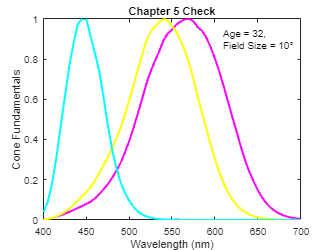

checkType = "Allie"; % "CIE"

% Draw graph
% Dana
for cone = 1:length(cones)
    x = wavelengths;
    y = cone_fundamentals_tbl(:,cone);
    plot(x, y, "LineWidth", 2, "Color", cones(cone))
    hold on
end

% Check
colours = ['m', 'y', 'c'];

if strcmpi(checkType, "Allie")
    addpath("Conversion-Code\Allie\CIE2006\");
    addpath("Conversion-Code\Allie\CIE2006\functions\");
    coneFun = reconstructingConeFundamentals(age, field_size);
    coneNames = ["eL", "eM", "eS"];
    for cone = 1:length(cones)
        x = coneFun.wavelengths;
        y = coneFun.(coneNames(cone));
        plot(x, y, "LineWidth", 2, "Color", colours(cone))
        hold on
    end

elseif strcmpi(checkType, "CIE")
    check_10 = table2array(readtable("linss10e_5.csv"));
    check_10 = check_10(idx,2:end);
    for cone = 1:length(cones)
        x = wavelengths;
        y = check_10(:,cone);
        plot(x, y, "LineWidth", 2, "Color", colours(cone))
        hold on
    end 

else
    disp("Enter ""Allie"" or ""CIE"" for the comparison data!");
end

% Graph layout
ylim([0, 1]);
xlim([min(x), max(x)]);
xlabel("Wavelength (nm)");
ylabel("Cone Fundamentals");
title("Chapter 5 Check");
text(610, .9, strjoin(["Age = ", age, "," newline, "Field Size = ", field_size, "°"],''));
hold off